# Viscous Nutation Damper

rotMats = {@(ang)[1,0,0;0,cos(ang),sin(ang);0,-sin(ang),cos(ang)],...
    @(ang)[cos(ang),0,-sin(ang);0,1,0;sin(ang),0,cos(ang)],...
   @(ang)[cos(ang),sin(ang),0;-sin(ang),cos(ang),0;0,0,1]};
syms omega_1(t) omega_2(t) omega_3(t) Omega(t)
syms I_1 I_W I_S I_T M1 M2 D 'real'
syms w1d w2d w3d Od w1 w2 w3 O IsIt IwIt DIt 'real'

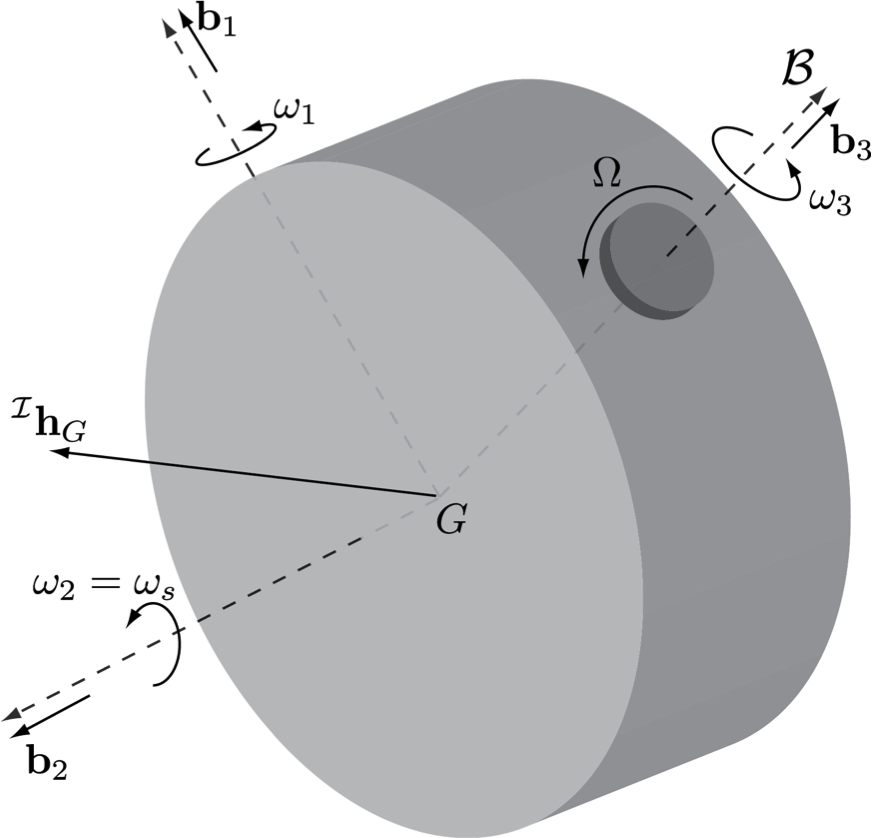

Define total and wheel MOI in $\mathcal B$ frame (about respective centers of mass):

Isat_B = diag([I_T,I_S,I_T])

$$Isat\_B = \left(\begin{array}{ccc} I_{T} & 0 & 0\\ 0 & I_{S} & 0\\ 0 & 0 & I_{T} \end{array}\right)$$

Iwheel_B = diag([I_1,I_1,I_W])

$$Iwheel\_B = \left(\begin{array}{ccc} I_{1} & 0 & 0\\ 0 & I_{1} & 0\\ 0 & 0 & I_{W} \end{array}\right)$$

Define $${}^\mathcal{I}{\omega}^\mathcal{B}$$ and $${}^\mathcal{B}{\omega}^\mathcal{A}$$ where $$\mathcal A$$ is the frame fixed to the wheel ($$\mathbf b_3 \equiv \mathbf a_3$$):

iWb = [omega_1,omega_2,omega_3].'

$$iWb(t) = \left(\begin{array}{c} \omega_{1}\left(t\right)\\ \omega_{2}\left(t\right)\\ \omega_{3}\left(t\right) \end{array}\right)$$

bWa = [0,0,Omega].'

$$bWa(t) = \left(\begin{array}{c} 0\\ 0\\ \Omega \left(t\right) \end{array}\right)$$

Calculate total inertial angular momentum and angular momentum of the wheel:

hG_sat = Isat_B*iWb + Iwheel_B*bWa

$$hG\_sat(t) = \left(\begin{array}{c} I_{T}\,\omega_{1}\left(t\right)\\ I_{S}\,\omega_{2}\left(t\right)\\ I_{W}\,\Omega \left(t\right)+I_{T}\,\omega_{3}\left(t\right) \end{array}\right)$$

hG_wheel = Iwheel_B*(bWa+iWb)

$$hG\_wheel(t) = \left(\begin{array}{c} I_{1}\,\omega_{1}\left(t\right)\\ I_{1}\,\omega_{2}\left(t\right)\\ I_{W}\,\left(\Omega \left(t\right)+\omega_{3}\left(t\right)\right) \end{array}\right)$$

Set up the systems of differential equations for the whole satellite assuming no external torques: ${}^\mathcal{I}\frac{\mathrm{d}}{\mathrm{d}t}{}^\mathcal{I} \mathbf{h}_G^\mathrm{tot} = 0$

eq1 = diff(hG_sat,t) + cross(iWb,hG_sat)

$$eq1(t) = \begin{array}{l} \left(\begin{array}{c} I_{T}\,\frac{\partial }{\partial t}\omega_{1}\left(t\right)+\omega_{2}\left(t\right)\,\sigma_{1}-I_{S}\,\omega_{2}\left(t\right)\,\omega_{3}\left(t\right)\\ I_{S}\,\frac{\partial }{\partial t}\omega_{2}\left(t\right)-\omega_{1}\left(t\right)\,\sigma_{1}+I_{T}\,\omega_{1}\left(t\right)\,\omega_{3}\left(t\right)\\ I_{W}\,\frac{\partial }{\partial t}\Omega \left(t\right)+I_{T}\,\frac{\partial }{\partial t}\omega_{3}\left(t\right)+I_{S}\,\omega_{1}\left(t\right)\,\omega_{2}\left(t\right)-I_{T}\,\omega_{1}\left(t\right)\,\omega_{2}\left(t\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=I_{W}\,\Omega \left(t\right)+I_{T}\,\omega_{3}\left(t\right) \end{array}$$

Set up the system of differential equations for the nutation damper assuming$ $-D\Omega$ $  internal torque about the wheel spin axis, and arbitrary torques $M_1,M_2$ about the transverse axes: ${}^\mathcal{I}\frac{\mathrm{d}}{\mathrm{d}t}{}^\mathcal{I} \mathbf{h}_G^\mathrm{wheel} +D\Omega\mathbf{\hat{b}}_3 - M_1\mathbf{\hat{b}}_1 - M_2\mathbf{\hat{b}}_2 = 0$

eq2 = diff(hG_wheel,t) + cross(iWb,hG_wheel) - [M1,M2,-D*Omega].'

$$eq2(t) = \begin{array}{l} \left(\begin{array}{c} I_{1}\,\frac{\partial }{\partial t}\omega_{1}\left(t\right)-M_{1}-I_{1}\,\omega_{2}\left(t\right)\,\omega_{3}\left(t\right)+I_{W}\,\omega_{2}\left(t\right)\,\sigma_{1}\\ I_{1}\,\frac{\partial }{\partial t}\omega_{2}\left(t\right)-M_{2}+I_{1}\,\omega_{1}\left(t\right)\,\omega_{3}\left(t\right)-I_{W}\,\omega_{1}\left(t\right)\,\sigma_{1}\\ I_{W}\,\left(\frac{\partial }{\partial t}\Omega \left(t\right)+\frac{\partial }{\partial t}\omega_{3}\left(t\right)\right)+\text{D}\,\Omega \left(t\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\Omega \left(t\right)+\omega_{3}\left(t\right) \end{array}$$

eq1 = eq1(t);
eq2 = eq2(t);

Now we're going to substitute for the variables we wish to solve for, set up the system of 4 equations in the four unknowns, and then solve:

sys = [eq1;eq2(3)]

$$sys = \begin{array}{l} \left(\begin{array}{c} I_{T}\,\frac{\partial }{\partial t}\omega_{1}\left(t\right)+\omega_{2}\left(t\right)\,\sigma_{1}-I_{S}\,\omega_{2}\left(t\right)\,\omega_{3}\left(t\right)\\ I_{S}\,\frac{\partial }{\partial t}\omega_{2}\left(t\right)-\omega_{1}\left(t\right)\,\sigma_{1}+I_{T}\,\omega_{1}\left(t\right)\,\omega_{3}\left(t\right)\\ I_{W}\,\frac{\partial }{\partial t}\Omega \left(t\right)+I_{T}\,\frac{\partial }{\partial t}\omega_{3}\left(t\right)+I_{S}\,\omega_{1}\left(t\right)\,\omega_{2}\left(t\right)-I_{T}\,\omega_{1}\left(t\right)\,\omega_{2}\left(t\right)\\ I_{W}\,\left(\frac{\partial }{\partial t}\Omega \left(t\right)+\frac{\partial }{\partial t}\omega_{3}\left(t\right)\right)+\text{D}\,\Omega \left(t\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=I_{W}\,\Omega \left(t\right)+I_{T}\,\omega_{3}\left(t\right) \end{array}$$

sys = subs(sys,[diff(omega_1,t),diff(omega_2,t),diff(omega_3,t),diff(Omega,t)],[w1d,w2d,w3d,Od])

$$sys = \begin{array}{l} \left(\begin{array}{c} I_{T}\,\mathrm{w1d}+\omega_{2}\left(t\right)\,\sigma_{1}-I_{S}\,\omega_{2}\left(t\right)\,\omega_{3}\left(t\right)\\ I_{S}\,\mathrm{w2d}-\omega_{1}\left(t\right)\,\sigma_{1}+I_{T}\,\omega_{1}\left(t\right)\,\omega_{3}\left(t\right)\\ I_{T}\,\mathrm{w3d}+I_{W}\,\mathrm{Od}+I_{S}\,\omega_{1}\left(t\right)\,\omega_{2}\left(t\right)-I_{T}\,\omega_{1}\left(t\right)\,\omega_{2}\left(t\right)\\ \text{D}\,\Omega \left(t\right)+I_{W}\,\left(\mathrm{Od}+\mathrm{w3d}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=I_{W}\,\Omega \left(t\right)+I_{T}\,\omega_{3}\left(t\right) \end{array}$$

sol = solve(sys,[w1d,w2d,w3d,Od],'ReturnConditions',true)

sol = struct with fields:
           w1d: [1×1 sym]
           w2d: [1×1 sym]
           w3d: [1×1 sym]
            Od: [1×1 sym]
    parameters: [1×0 sym]
    conditions: [1×1 sym]


Let's take a look at the equations of motion:

sol.w1d, sol.w2d, sol.w3d, sol.Od

$$ans = -\frac{I_{W}\,\Omega \left(t\right)\,\omega_{2}\left(t\right)-I_{S}\,\omega_{2}\left(t\right)\,\omega_{3}\left(t\right)+I_{T}\,\omega_{2}\left(t\right)\,\omega_{3}\left(t\right)}{I_{T}}$$

$$ans = \frac{I_{W}\,\Omega \left(t\right)\,\omega_{1}\left(t\right)}{I_{S}}$$

$$ans = \frac{\text{D}\,\Omega \left(t\right)-I_{S}\,\omega_{1}\left(t\right)\,\omega_{2}\left(t\right)+I_{T}\,\omega_{1}\left(t\right)\,\omega_{2}\left(t\right)}{I_{T}-I_{W}}$$

$$ans = -\frac{\text{D}\,I_{T}\,\Omega \left(t\right)-I_{S}\,I_{W}\,\omega_{1}\left(t\right)\,\omega_{2}\left(t\right)+I_{T}\,I_{W}\,\omega_{1}\left(t\right)\,\omega_{2}\left(t\right)}{I_{W}\,\left(I_{T}-I_{W}\right)}$$

Notice that the EOMs are all function of ratios $I_S/I_T, I_W/I_T, D/I_T$.  Lets set up a new system of equivalent equations, but with these terms substituted as variables.

sys2 = [simplify(subs(expand(sol.w1d),[I_S/I_T,I_W/I_T,I_W/I_S],[IsIt,IwIt,IwIt/IsIt]));...
    simplify(subs(expand(sol.w2d),[I_S/I_T,I_W/I_T,I_W/I_S],[IsIt,IwIt,IwIt/IsIt]));...
    (DIt*Omega - (IsIt - 1)*omega_1*omega_2)/(1 - IwIt);...
    ((IsIt - 1)*omega_1*omega_2 - DIt/IwIt*Omega)/(1 - IwIt)]

$$sys2(t) = \left(\begin{array}{c} -\omega_{2}\left(t\right)\,\left(\omega_{3}\left(t\right)+\mathrm{IwIt}\,\Omega \left(t\right)-\mathrm{IsIt}\,\omega_{3}\left(t\right)\right)\\ \frac{\mathrm{IwIt}\,\Omega \left(t\right)\,\omega_{1}\left(t\right)}{\mathrm{IsIt}}\\ -\frac{\mathrm{DIt}\,\Omega \left(t\right)-\omega_{1}\left(t\right)\,\omega_{2}\left(t\right)\,\left(\mathrm{IsIt}-1\right)}{\mathrm{IwIt}-1}\\ \frac{\frac{\mathrm{DIt}\,\Omega \left(t\right)}{\mathrm{IwIt}}-\omega_{1}\left(t\right)\,\omega_{2}\left(t\right)\,\left(\mathrm{IsIt}-1\right)}{\mathrm{IwIt}-1} \end{array}\right)$$

 sys2 = sys2(t)

$$sys2 = \left(\begin{array}{c} -\omega_{2}\left(t\right)\,\left(\omega_{3}\left(t\right)+\mathrm{IwIt}\,\Omega \left(t\right)-\mathrm{IsIt}\,\omega_{3}\left(t\right)\right)\\ \frac{\mathrm{IwIt}\,\Omega \left(t\right)\,\omega_{1}\left(t\right)}{\mathrm{IsIt}}\\ -\frac{\mathrm{DIt}\,\Omega \left(t\right)-\omega_{1}\left(t\right)\,\omega_{2}\left(t\right)\,\left(\mathrm{IsIt}-1\right)}{\mathrm{IwIt}-1}\\ \frac{\frac{\mathrm{DIt}\,\Omega \left(t\right)}{\mathrm{IwIt}}-\omega_{1}\left(t\right)\,\omega_{2}\left(t\right)\,\left(\mathrm{IsIt}-1\right)}{\mathrm{IwIt}-1} \end{array}\right)$$

Now we can numerically integrate. Create a lambda function for the equations of motion:

  sys2 = subs(sys2,[omega_1,omega_2,omega_3,Omega],[w1,w2,w3,O])

$$sys2 = \left(\begin{array}{c} -w_{2}\,\left(w_{3}-\mathrm{IsIt}\,w_{3}+\mathrm{IwIt}\,\text{O}\right)\\ \frac{\mathrm{IwIt}\,\text{O}\,w_{1}}{\mathrm{IsIt}}\\ -\frac{\mathrm{DIt}\,\text{O}-w_{1}\,w_{2}\,\left(\mathrm{IsIt}-1\right)}{\mathrm{IwIt}-1}\\ \frac{\frac{\mathrm{DIt}\,\text{O}}{\mathrm{IwIt}}-w_{1}\,w_{2}\,\left(\mathrm{IsIt}-1\right)}{\mathrm{IwIt}-1} \end{array}\right)$$

f1 = matlabFunction(sys2,'vars',{w1,w2,w3,O,IwIt,IsIt,DIt})

f1 = function_handle with value:
    @(w1,w2,w3,O,IwIt,IsIt,DIt)[-w2.*(w3-IsIt.*w3+IwIt.*O);(IwIt.*O.*w1)./IsIt;-(DIt.*O-w1.*w2.*(IsIt-1.0))./(IwIt-1.0);((DIt.*O)./IwIt-w1.*w2.*(IsIt-1.0))./(IwIt-1.0)]


Let's set $I_W/I_T = 0.06, I_S/I_T = 1.5, D/I_T = 0.5$

 f2 = @(t,z) f1(z(1),z(2),z(3),z(4),0.06,1.5,0.5)

f2 = function_handle with value:
    @(t,z)f1(z(1),z(2),z(3),z(4),0.06,1.5,0.5)


We'll set initial conditions simulating an angular impulse creating a small component of spin about $\mathbf{\hat{b}}_1$ in addition to the primary spin about $\mathbf{\hat{b}}_2$.  The nutation damper is initially at rest ($\Omega = 0$).

 [T,Z] = ode45(f2,[0,400],[0.2,2,0,0]);

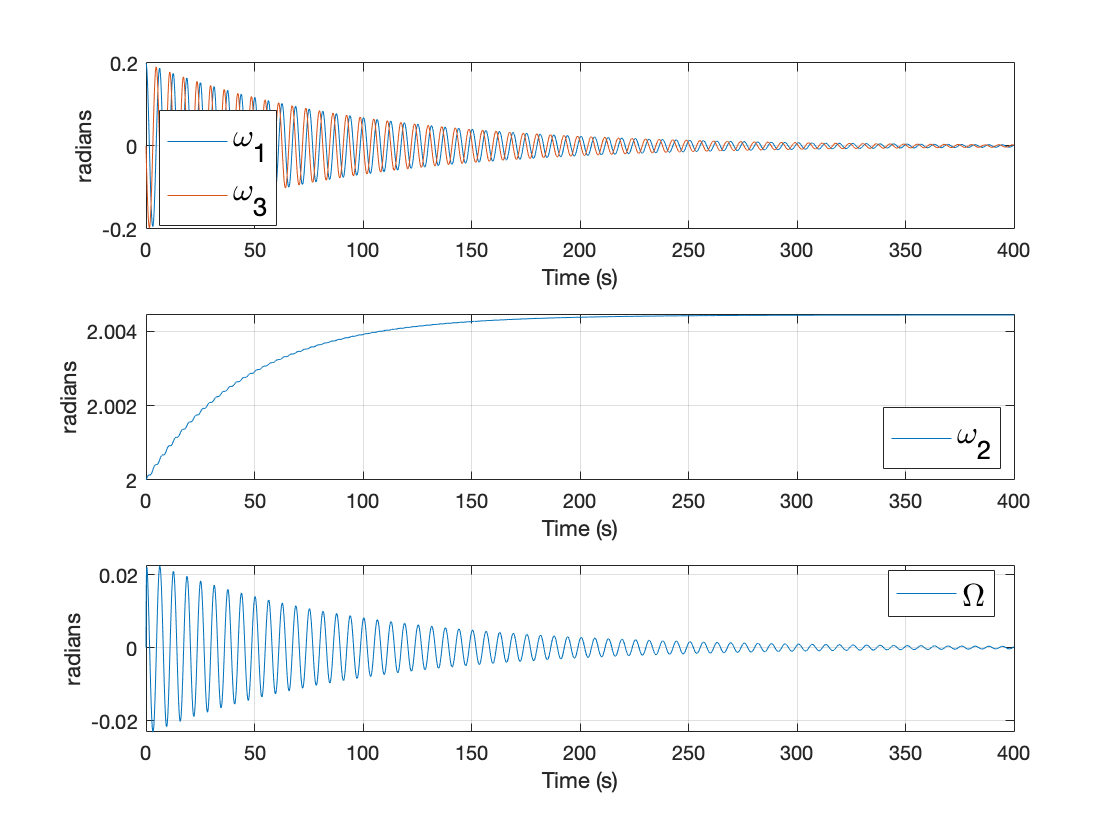

subplot(3,1,1)
plot(T,Z(:,[1,3]))
grid on
ylabel('radians')
xlabel('Time (s)')
legend({'\omega_1','\omega_3'},'FontSize',16,'Location','best')
subplot(3,1,2)
plot(T,Z(:,2))
grid on
ylabel('radians')
xlabel('Time (s)')
legend({'\omega_2'},'FontSize',16,'Location','best')
subplot(3,1,3)
plot(T,Z(:,4))
grid on
ylabel('radians')
xlabel('Time (s)')
legend({'\Omega'},'FontSize',16,'Location','best')

With $I_S/I_T > 1$, we got exactly the desired beavior (damping out of the disturbance angular impulse).  Now, let's see what happens with $I_S/I_T < 1$

f3 = @(t,z) f1(z(1),z(2),z(3),z(4),0.06,1/1.5,0.5)

f3 = function_handle with value:
    @(t,z)f1(z(1),z(2),z(3),z(4),0.06,1/1.5,0.5)


[T2,Z2] = ode45(f3,[0,400],[0.2,2,0,0]);

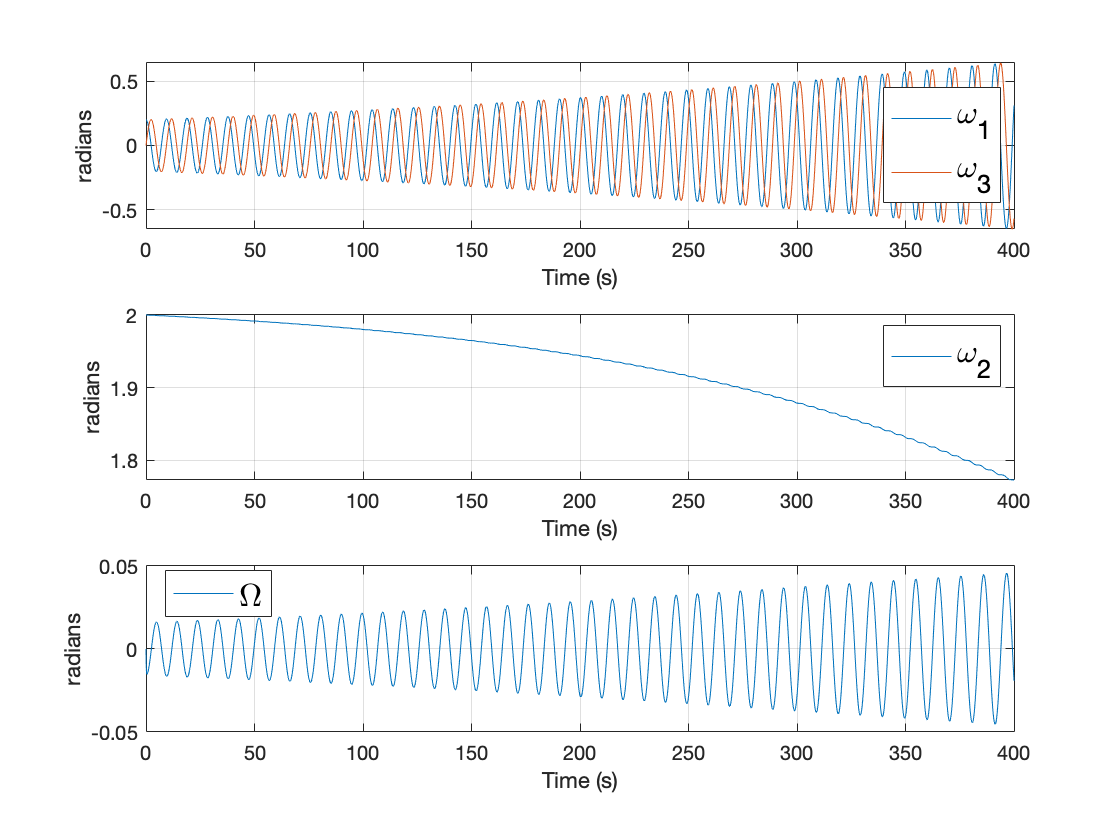

subplot(3,1,1)
plot(T2,Z2(:,[1,3]))
grid on
ylabel('radians')
xlabel('Time (s)')
legend({'\omega_1','\omega_3'},'FontSize',16,'Location','best')
subplot(3,1,2)
plot(T2,Z2(:,2))
grid on
ylabel('radians')
xlabel('Time (s)')
legend({'\omega_2'},'FontSize',16,'Location','best')
subplot(3,1,3)
plot(T2,Z2(:,4))
grid on
ylabel('radians')
xlabel('Time (s)')
legend({'\Omega'},'FontSize',16,'Location','best')

In this case, the initial disturbance does not damp out, but is instead magnified!